clear all
clc;

## Radar Specifications

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%speed of light = 3e8

c=3e8;
Rres=1;
Rmax=200;
vmax=100;
vres=3;

% User Defined Range and Velocity of Target

% define the target's initial position and velocity. Note : Velocity remains contant
R=50; % target range
v=20; % target velocity

## FMCW Waveform Generation

% Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the FMCW
% chirp using the requirements above.
B=c/(2*Rres);
Tchirp=5.5*2*(Rmax/c);
slope=B/Tchirp

slope = 2.0455e+13


%Operating carrier frequency of Radar 
fc = 77e9;             %carrier freq
                                                          
% The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
% for Doppler Estimation. 
Nd = 128;                   % #of doppler cells OR #of sent periods % number of chirps

% The number of samples on each chirp. 
Nr = 1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t = linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
r_t=zeros(1,length(t));
td=zeros(1,length(t));

## Signal generation and Moving Target simulation

Running the radar scenario over the time. 

for i=1:length(t)         
    
    
    % *%TODO* :
    %For each time stamp update the Range of the Target for constant velocity. 
    r_t(i)=R+v*t(i);
    
    % For each time sample we need update the transmitted and
    % received signal. 
    td(i) = 2*r_t(i)/c;
    Tx(i) = cos(2*pi*(fc*t(i) + (slope*t(i)^2)/2));
    Rx(i) = cos(2*pi*(fc*(t(i)-td(i)) + (slope*(t(i)-td(i))^2)/2));
    
    % Now by mixing the Transmit and Receive generate the beat signal
    % This is done by element wise matrix multiplication of Transmit and
    % Receiver Signal
    Mix(i) = Tx(i).*Rx(i);
    
end

## RANGE MEASUREMENT

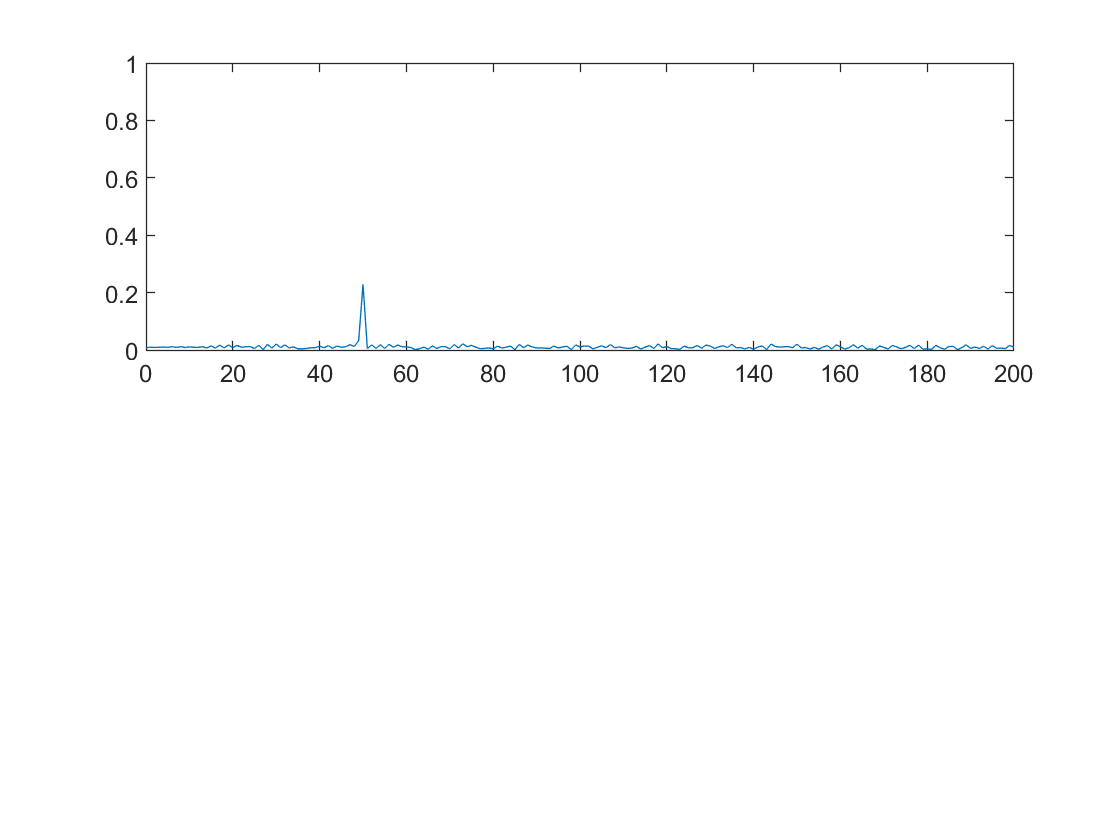

% reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
% Range and Doppler FFT respectively.
Mix = reshape(Mix, [Nr, Nd]);

% run the FFT on the beat signal along the range bins dimension (Nr) and
% normalize.
Mix_fft = fft(Mix, Nr);

% Take the absolute value of FFT output
L = Tchirp*B; % signal length
Mix_fft = abs(Mix_fft/L);

% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
Mix_fft = Mix_fft(1:(L/2+1));


% Plotting the range
figure ('Name','Range from First FFT')
subplot(2,1,1)

% plot FFT output 
Fs=c*Tchirp/2; % sampling frequency
f=(Fs*(0:(L/2)))/L;
plot(f, Mix_fft);
axis ([0 200 0 1]);

## RANGE DOPPLER RESPONSE

The 2D FFT implementation is already provided here. This will run a 2DFFT on the mixed signal (beat signal) output and generate a range doppler map.You will implement CFAR on the generated RDM

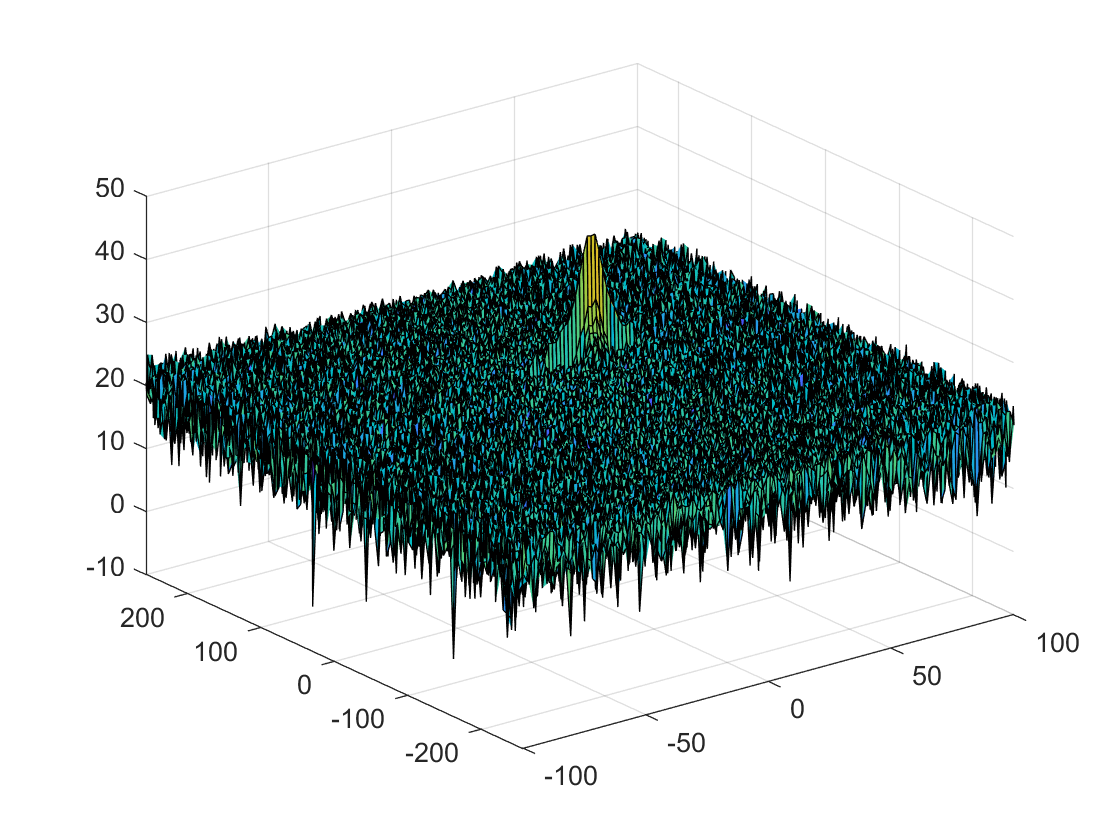

% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
Mix_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
Mix_fft2 = Mix_fft2(1:Nr/2,1:Nd);
Mix_fft2 = fftshift (Mix_fft2);
RDM = abs(Mix_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);

## CFAR implementation

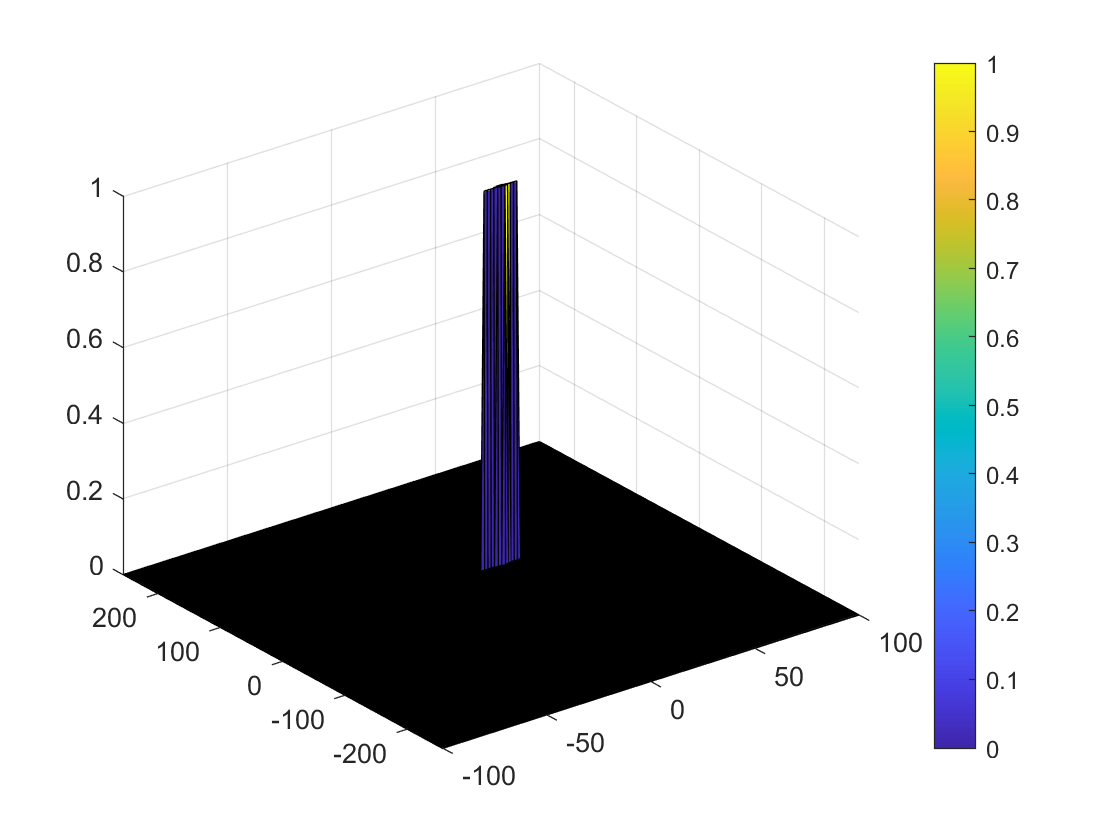

%Slide Window through the complete Range Doppler Map

% Select the number of Training Cells in both the dimensions.
Tr = 10;
Td = 5;

% Select the number of Guard Cells in both dimensions around the Cell under 
% test (CUT) for accurate estimation
Gr = 5;
Gd = 3;

% offset the threshold by SNR value in dB
SNR = 6;

% *%TODO* :
%Create a vector to store noise_level for each iteration on training cells
noise_level = zeros(1,1);

% design a loop such that it slides the CUT across range doppler map by
% giving margins at the edges for Training and Guard Cells.
% For every iteration sum the signal level within all the training
% cells. To sum convert the value from logarithmic to linear using db2pow
% function. Average the summed values for all of the training
% cells used. After averaging convert it back to logarithimic using pow2db.
% Further add the offset to it to determine the threshold. Next, compare the
% signal under CUT with this threshold. If the CUT level > threshold assign
% it a value of 1, else equate it to 0.
Mix_cfar = zeros(Nr/2, Nd);
filter_size = (2*Tr+2*Gr+1)*(2*Td+2*Gd+1)-(2*Gr+1)*(2*Gd+1);
for r = 1:(Nr/2-(2*Gr+2*Tr))
    for d = 1:(Nd-(2*Gd+2*Td))
        % Use RDM[x,y] as the matrix from the output of 2D FFT for implementing
        % CFAR
        sum_of_Ts = sum(db2pow( RDM(r:(r+2*Tr+2*Gr), d:(d+2*Td+2*Gd)) ), "all");
        sum_of_Gs = sum(db2pow( RDM((r+Tr):(r+Tr+2*Gr), (d+Td):(d+Td+2*Gd)) ), "all");
        noise_level = sum_of_Ts-sum_of_Gs;
        threshold = db2pow(pow2db(noise_level/filter_size) + SNR);
        signal = db2pow(RDM(r+Tr+Gr, d+Td+Gd));
        if signal <= threshold
            signal = 0;
        else
            signal = 1;
        end
        Mix_cfar(r+Tr+Gr, d+Td+Gd) = signal;
    end
end 


% The process above will generate a thresholded block, which is smaller 
% than the Range Doppler Map as the CUT cannot be located at the edges of
% matrix. Hence,few cells will not be thresholded. To keep the map size same
% set those values to 0. 
% ...-> already implemented by setting Mix_cfar to 0 everywhere on
% initialization

% display the CFAR output using the Surf function like we did for Range
% Doppler Response output.
figure,surf(doppler_axis,range_axis,Mix_cfar);
colorbar;